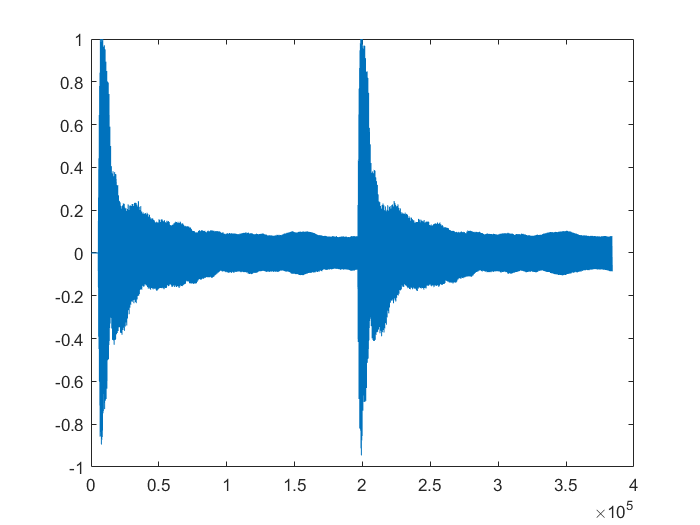

clc, clear

[x,fs]=audioread("agac.mp3");

y = x(1:8*fs,2);



%   fs = 44100;
%              recObj = audiorecorder(fs, 16, 2);
%              recordblocking(recObj, 4);
%              y0 = getaudiodata(recObj);
%             
%             sound(y0,fs)
%             y = y0(:,1);
            plot(y)

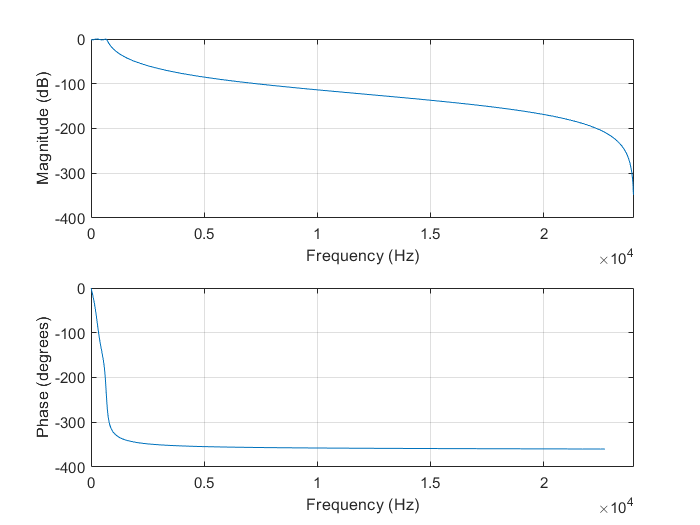

dp = 2;
f = 700;
Wp=f(1)/(fs/2);
[b, a] = cheby1(4,dp,Wp,'low');
freqz(b,a,1024, fs)

y1= filter(b,a,y);

g=fft(y1);
potencia=abs(g).^2;
df=1/(length(y)/fs);
f=(0:length(y)-1)*df; 
[r,k]=max(potencia);
fn=f(k)

fn = 82.1250

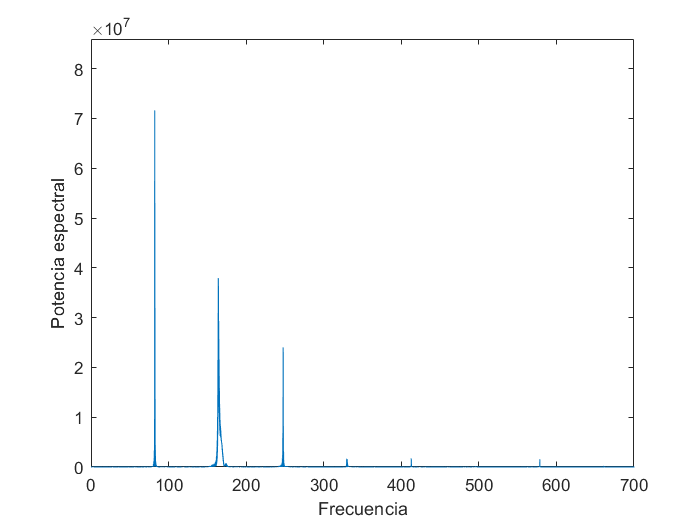


plot(f,potencia)
axis([0 700 0 r*1.2])
xlabel('Frecuencia')
ylabel('Potencia espectral')


L = 0.02*fs;
overlap = floor(0.9*L);
nfft = 2^nextpow2(L);
[pxx,f] = pwelch(y1,hamming(L),overlap,nfft,fs);
[pks, locs] = findpeaks(pxx,'SortStr','descend','NPeaks',1);
sort(f(locs))

ans = 187.5000